%% === SETUP ===
parent_folder = '/Users/shaheenkabir/Downloads/CantonS';
output_parent = '/Users/shaheenkabir/Downloads/CantonS/result';
if ~exist(output_parent, 'dir')
    mkdir(output_parent);
end

% === Pick single file ===
filename = fullfile(parent_folder, 'CantonS_25_5.tif');  % Change this
[~, baseName, ~] = fileparts(filename);

%Factor2 = 80/80;  % exposure correction
%Factor = 0.6431;  % micron/pixel

fprintf('Processing file: %s\n', filename);

Processing file: /Users/shaheenkabir/Downloads/CantonS/CantonS_25_5.tif


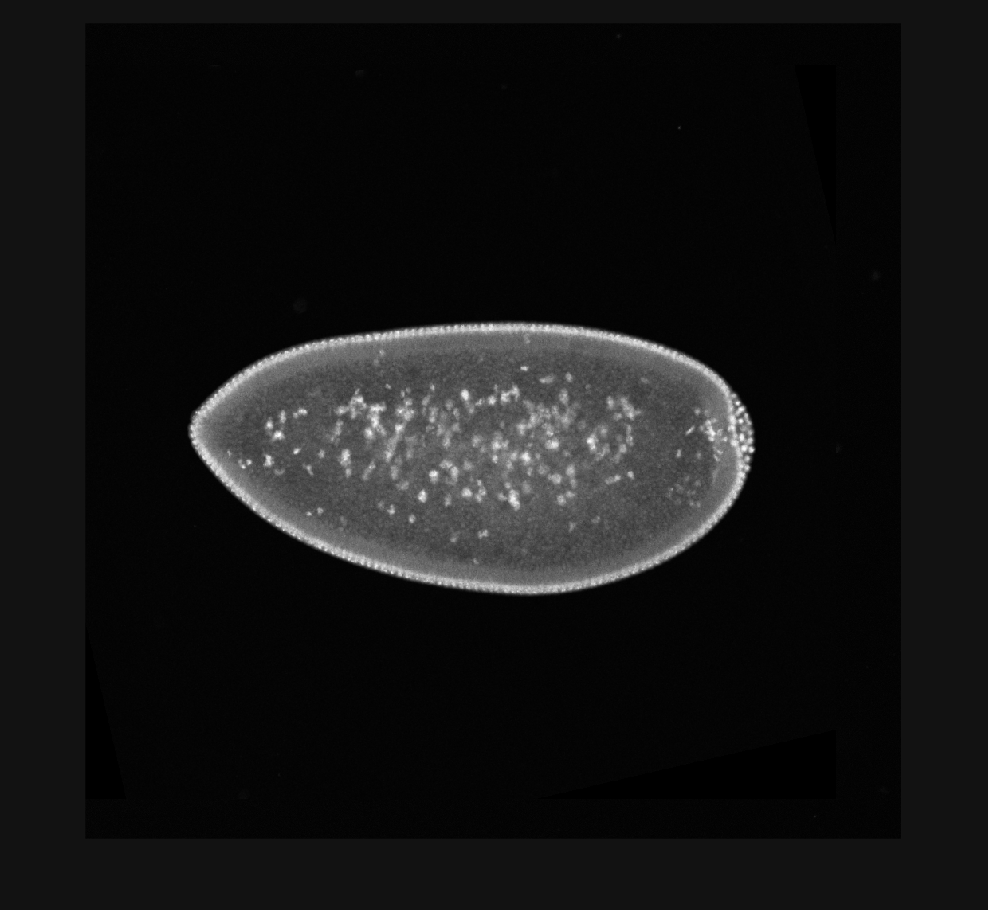


% === Create output folder ===
output_folder = fullfile(output_parent, baseName);
if ~exist(output_folder, 'dir')
    mkdir(output_folder);
end

%% === Load channels ===
DapiI = imread(filename, 1);
BcdI  = imread(filename, 2);
figure; imshow(DapiI);

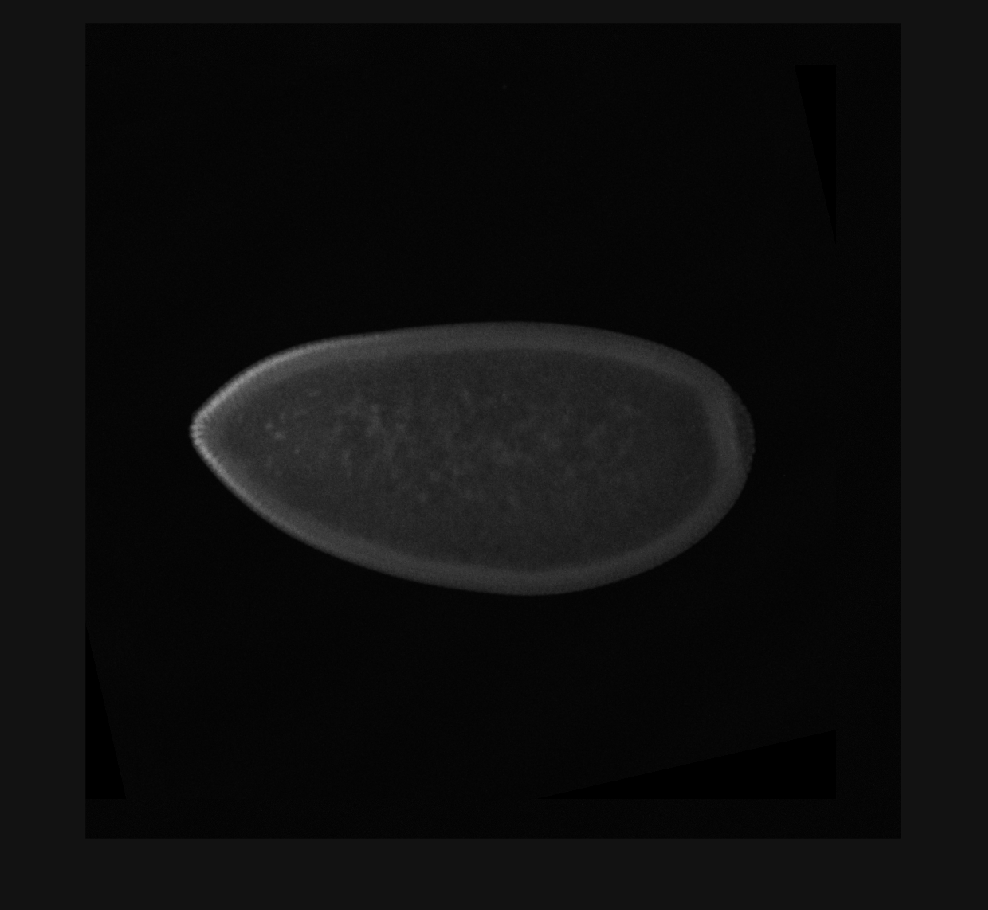

figure; imshow(BcdI);

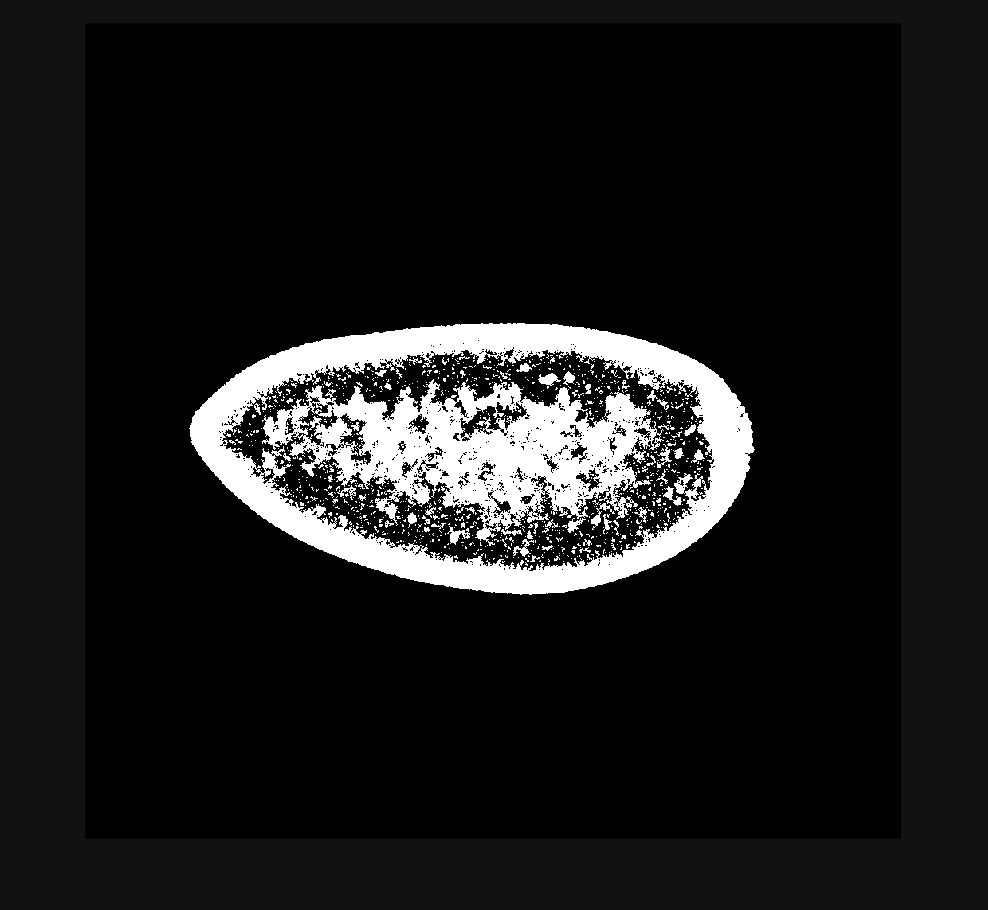

imwrite(DapiI, fullfile(output_folder, 'DapiI_raw.tif'));
imwrite(BcdI,  fullfile(output_folder, 'BcdI_raw.tif'));

%% === DAPI mask ===
DapiI = adapthisteq(DapiI);
treshold = graythresh(imadjust(DapiI));
%treshold = 0.44
mask = imbinarize(DapiI, treshold);
figure; imshow(mask);

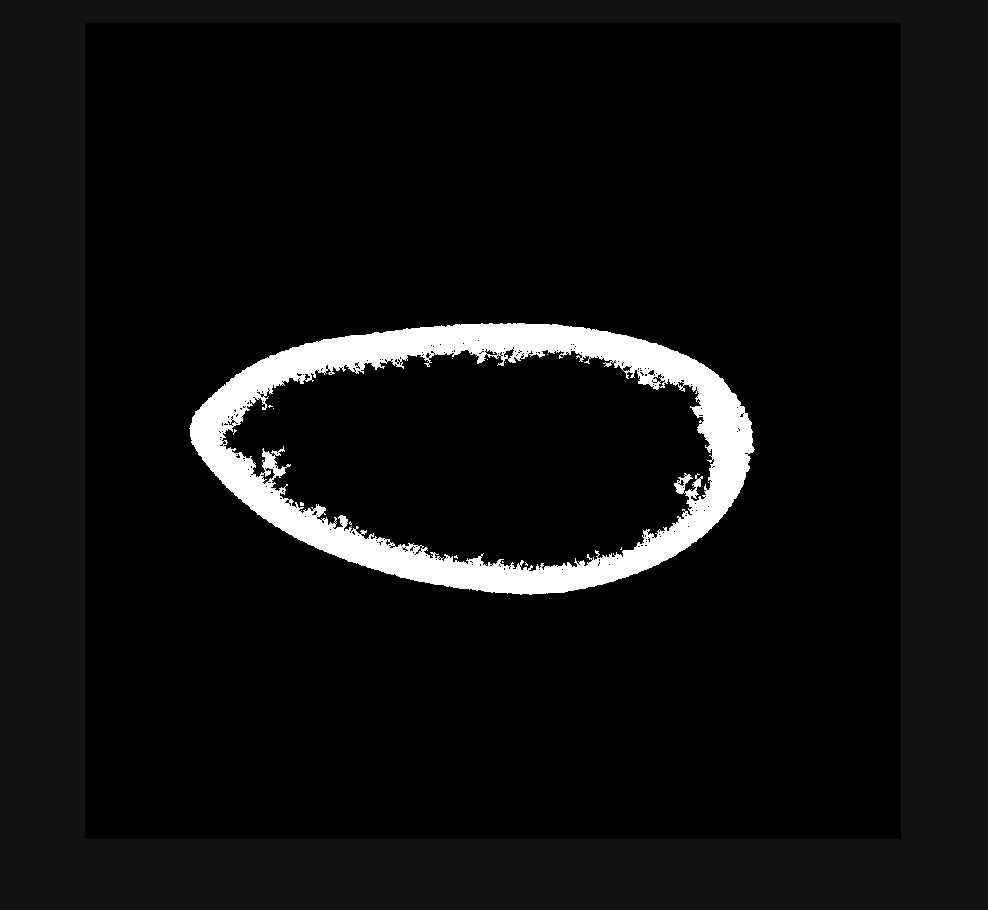

%imwrite(mask, fullfile(output_folder, 'mask.png'));

% === Largest embryo ===
stats = regionprops(mask, "all");
embryoArea = [stats.Area];
[~, embryoID] = max(embryoArea);

% === Nuclear mask ===
nmask = zeros(size(mask));
nmask(stats(embryoID).PixelIdxList) = 1;
figure; imshow(nmask);

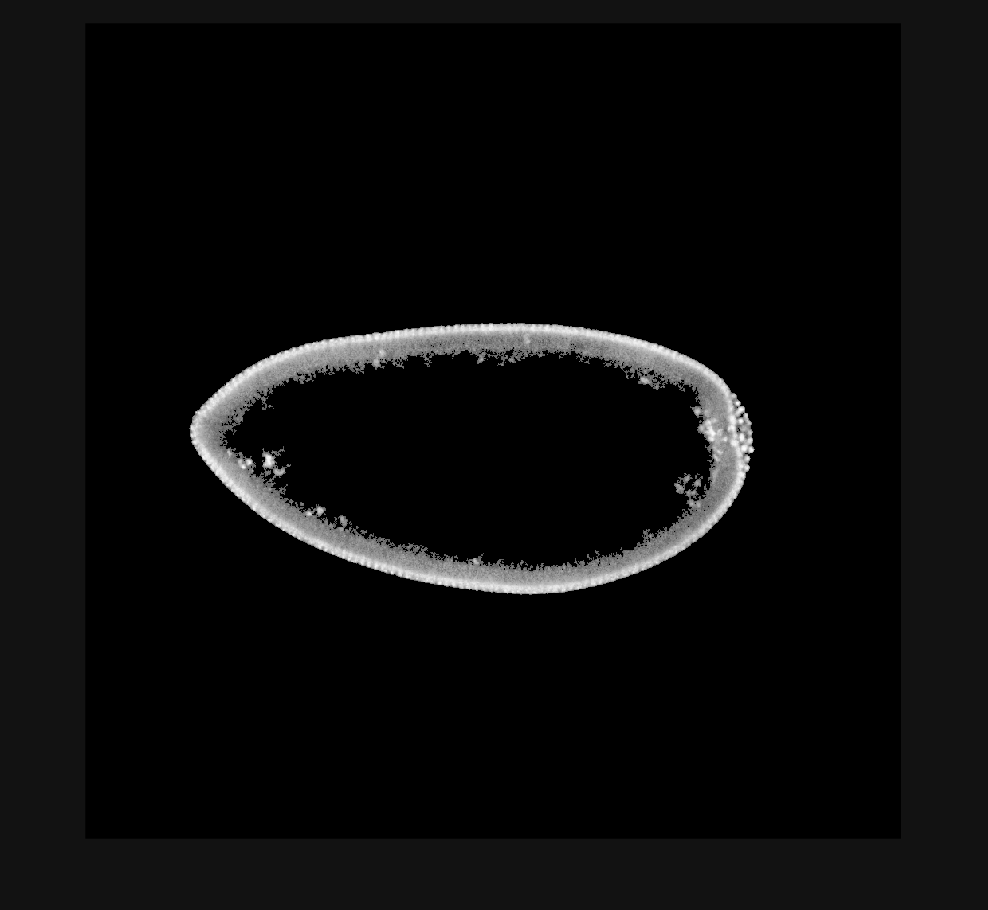

%imwrite(nmask, fullfile(output_folder, 'nmask.png'));

% === Apply nuclear mask ===
DapiI = DapiI .* uint8(nmask);
figure; imshow(DapiI);

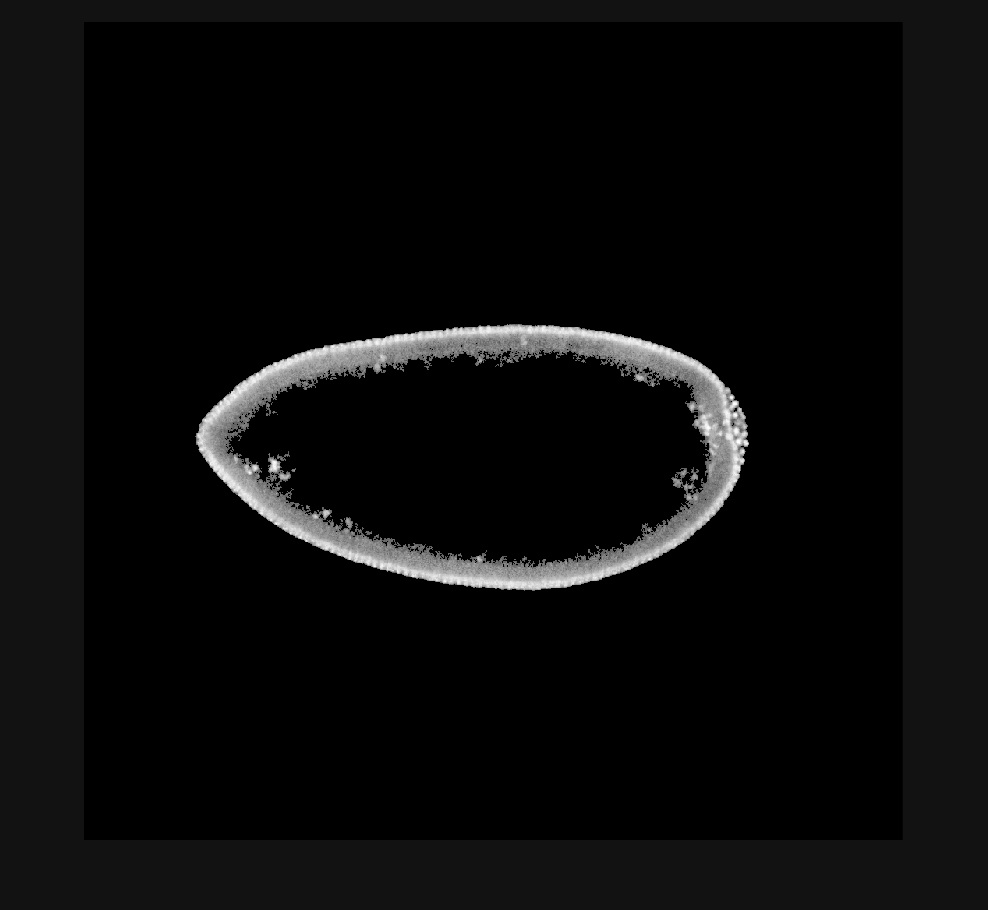

%imwrite(DapiI, fullfile(output_folder, 'DapiI_masked.png'));

% === Rotate and crop ===
theta = -stats(embryoID).Orientation;
DapiI = imrotate(DapiI, theta);
BcdI  = imrotate(BcdI, theta);
W     = imrotate(nmask, theta);

figure; imshow(DapiI);

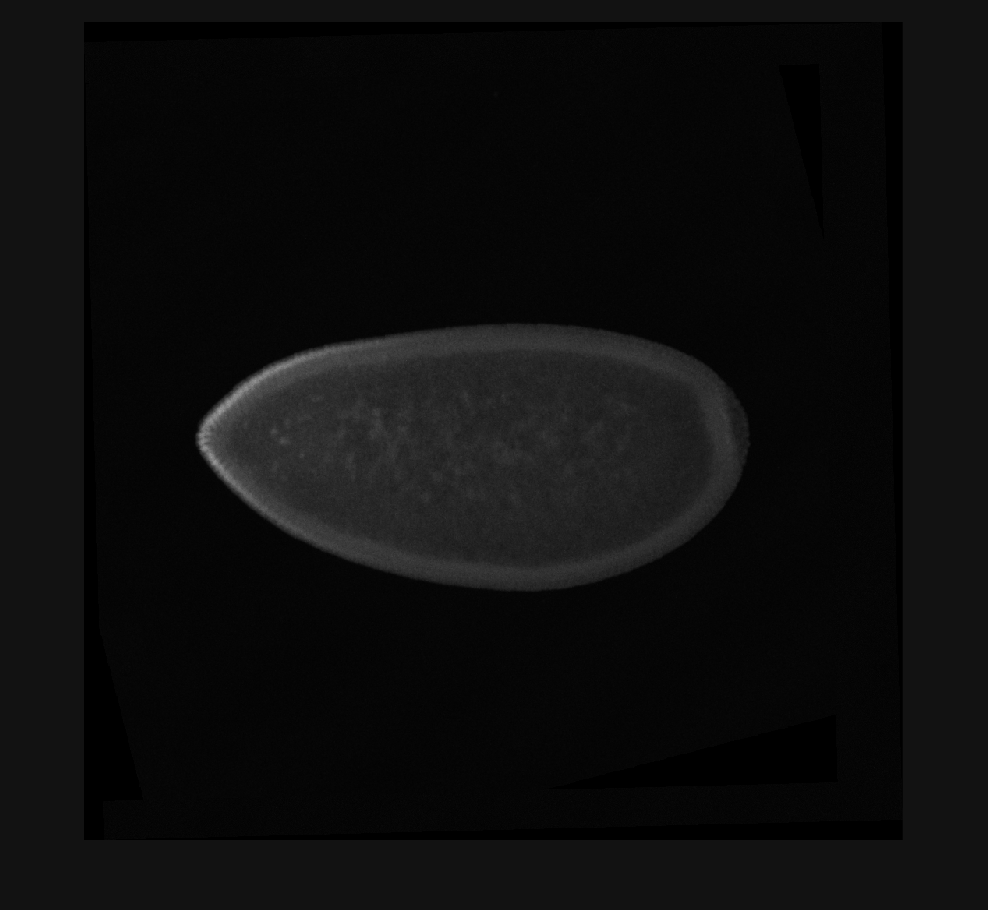

figure; imshow(BcdI);

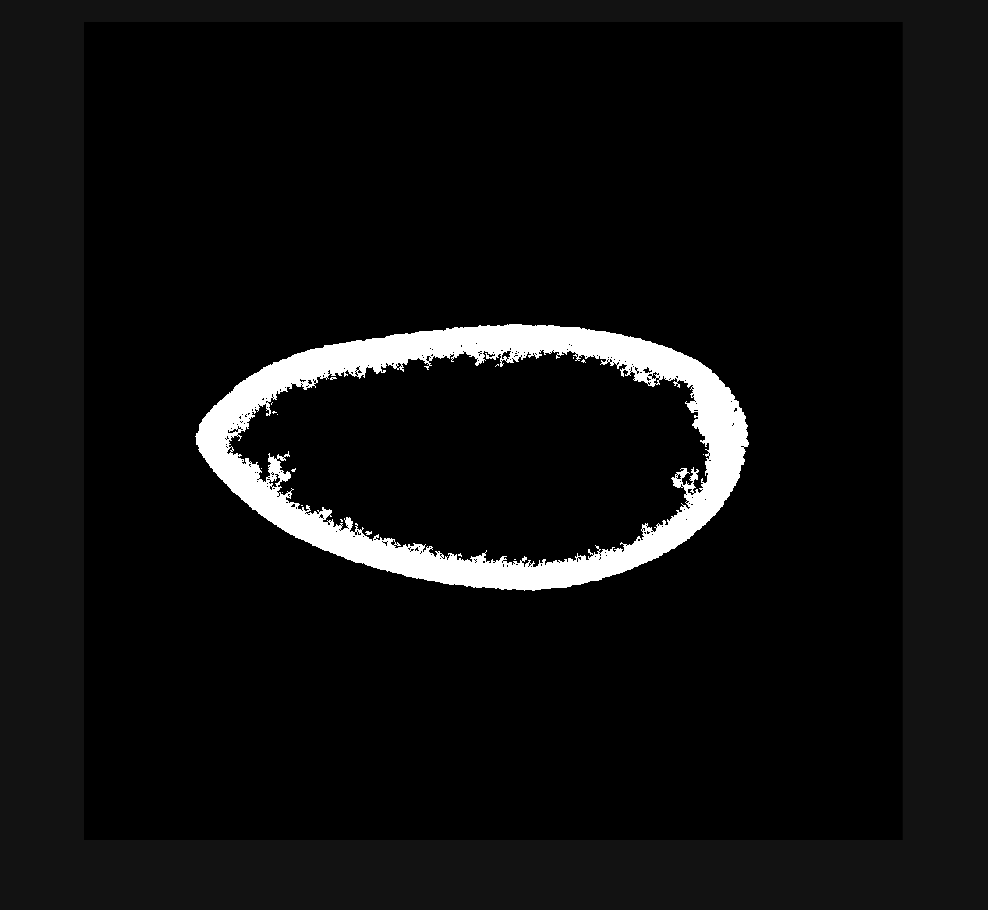

figure; imshow(W);

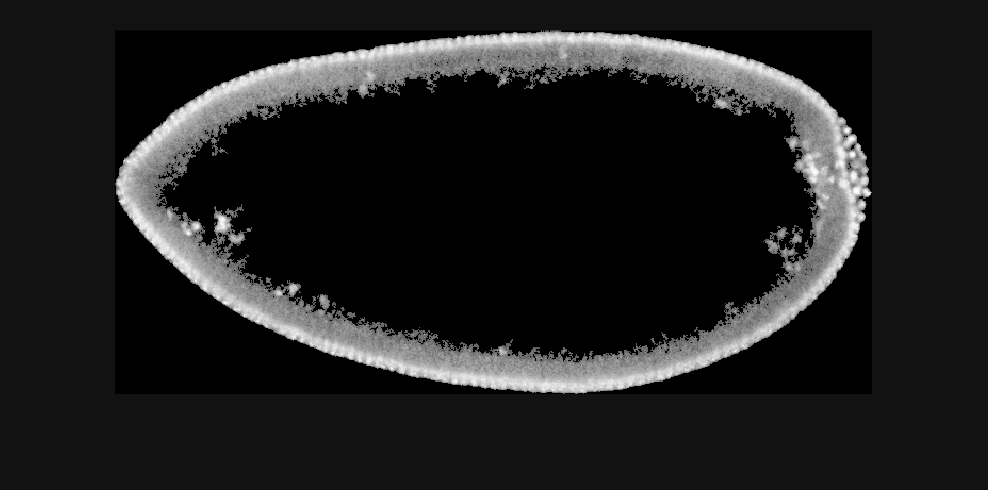

%imwrite(DapiI, fullfile(output_folder, 'DapiI_rotated.png'));
%imwrite(BcdI,  fullfile(output_folder, 'BcdI_rotated.png'));
%imwrite(W,     fullfile(output_folder, 'nmask_rotated.png'));

% Anterior-left, dorsal-up
BW = edge(W, 'canny');
imwrite(BW, fullfile(output_folder, 'nmask_edge.png'));
m0 = find(sum(BW, 1) > 0);
n0 = find(sum(BW, 2) > 0);

DapiI1 = imcrop(DapiI, [min(m0), min(n0), max(m0)-min(m0), max(n0)-min(n0)]);
BcdI1  = imcrop(BcdI, [min(m0), min(n0), max(m0)-min(m0), max(n0)-min(n0)]);
%theta2 = 180 * double(max(max(BcdI1(:,1:50))) < max(max(BcdI1(:,end-49:end))));
%DapiI1 = imrotate(DapiI1, theta2, 'crop');
%BcdI1  = imrotate(BcdI1, theta2, 'crop');
%imwrite(DapiI1, fullfile(output_folder, 'DapiI_final.png'));
%imwrite(BcdI1,  fullfile(output_folder, 'BcdI_final.png'));

figure; imshow(DapiI1);

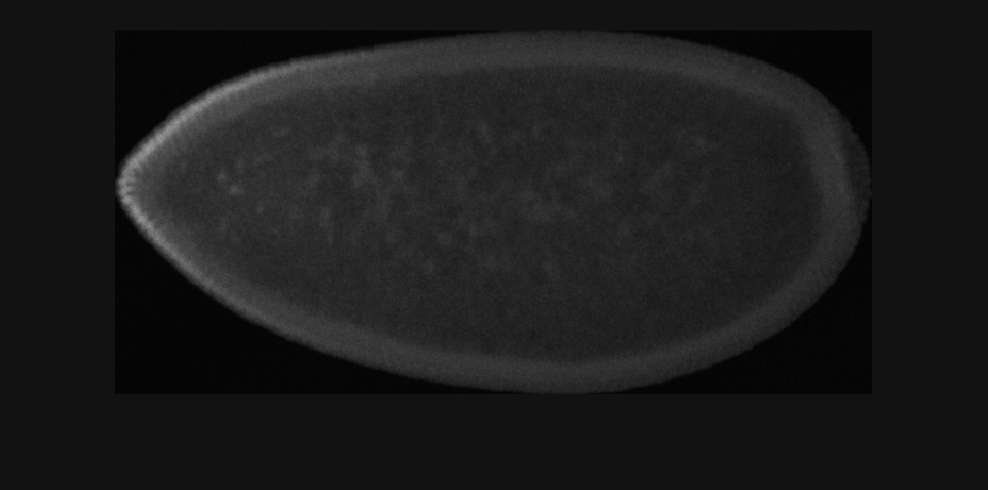

figure; imshow(BcdI1);

figure; imshow(W);

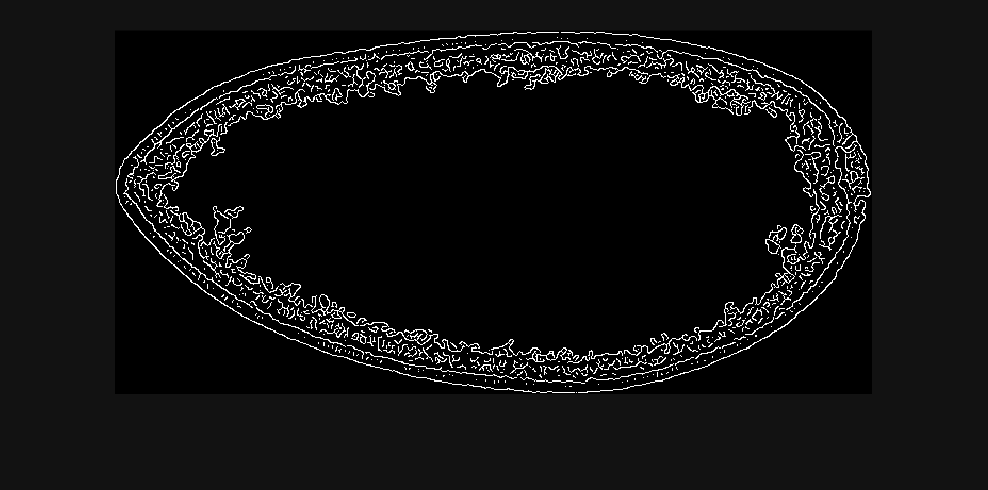


% === Find nuclear edge from DAPI ===
BW1 = edge(DapiI1, 'canny');
figure; imshow(BW1);

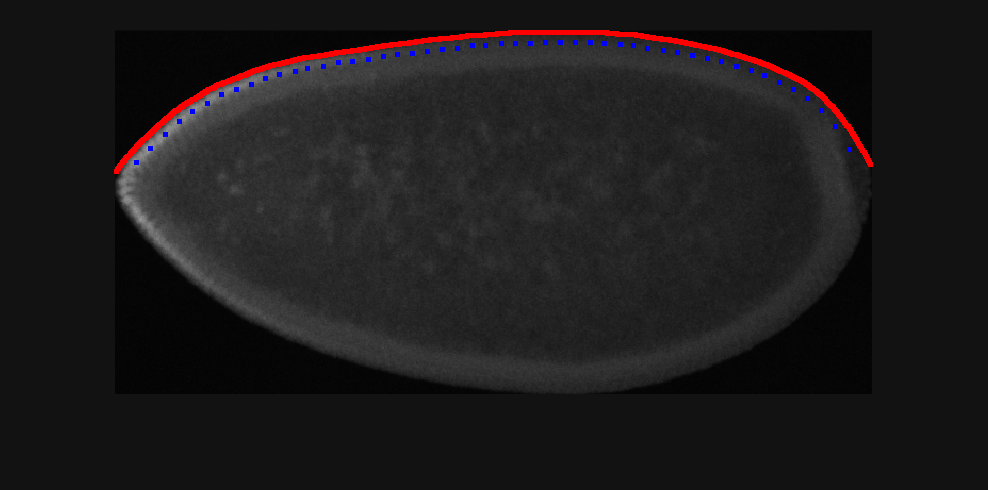

%imwrite(BW1, fullfile(output_folder, 'DapiI_edge.png'));

m1 = find(sum(BW1, 1) > 0);
n1 = zeros(1, length(m1));
for j = 1:length(m1)
    n1(j) = min(find(BW1(:, m1(j)) > 0));
end
n2 = smooth(m1, n1, 0.07, 'rloess')';

%% === Midline ===
Bins = 50;
EL = max(m1) - min(m1) + 1;
L = floor(EL / Bins);
gama = atan(gradient(n2));
radius = 10;
centroidx = round(m1 - sin(gama) * radius);
centroidy = round(n2 + cos(gama) * radius);

centroidx1 = zeros(1, Bins);
centroidy1 = zeros(1, Bins);
z = zeros(1, Bins);

for j = 1:Bins
    idx = ceil(0.5*EL - (Bins+1)/2*L + j*L);
    centroidx1(j) = centroidx(idx);
    centroidy1(j) = centroidy(idx);
    z(j) = mean2([BcdI1(centroidy1(j), centroidx1(j)-4:centroidx1(j)+4), ...
                  BcdI1(centroidy1(j)-1, centroidx1(j)-4:centroidx1(j)+3), ...
                  BcdI1(centroidy1(j)+1, centroidx1(j)-3:centroidx1(j)+4), ...
                  BcdI1(centroidy1(j)-2, centroidx1(j)-3:centroidx1(j)+3), ...
                  BcdI1(centroidy1(j)+2, centroidx1(j)-3:centroidx1(j)+3), ...
                  BcdI1(centroidy1(j)-3, centroidx1(j)-2:centroidx1(j)+3), ...
                  BcdI1(centroidy1(j)+3, centroidx1(j)-3:centroidx1(j)+2), ...
                  BcdI1(centroidy1(j)-4, centroidx1(j)-2:centroidx1(j)+2), ...
                  BcdI1(centroidy1(j)+4, centroidx1(j)-2:centroidx1(j)+2)]);
end

% === Save sampling scatter ===
figure; imshow(BcdI1); hold on;
scatter(m1, n2, 'r.');hold on;
scatter(centroidx1, centroidy1, 'b.');


f = figure; imshow(BcdI1); hold on;
scatter(m1, n2, 'r.');
scatter(centroidx1, centroidy1, 'b.');
saveas(f, fullfile(output_folder, 'sampling_points.png'));
close(f);

%saveas(f, fullfile(output_folder, 'sampling_points.png'));
%close(f);

%% === Absolute profile ===
L2 = round(900 / Bins);
Bins2 = floor(EL / L2);
z2 = zeros(1, Bins2);
centroidx2 = zeros(1, Bins2);
centroidy2 = zeros(1, Bins2);

for j = 1:Bins2
    idx = j*L2 - ceil(L2/2) + 1;
    centroidx2(j) = centroidx(idx);
    centroidy2(j) = centroidy(idx);
    z2(j) = mean2([BcdI1(centroidy2(j), centroidx2(j)-4:centroidx2(j)+4), ...
                   BcdI1(centroidy2(j)-1, centroidx2(j)-4:centroidx2(j)+3), ...
                   BcdI1(centroidy2(j)+1, centroidx2(j)-3:centroidx2(j)+4), ...
                   BcdI1(centroidy2(j)-2, centroidx2(j)-3:centroidx2(j)+3), ...
                   BcdI1(centroidy2(j)+2, centroidx2(j)-3:centroidx2(j)+3), ...
                   BcdI1(centroidy2(j)-3, centroidx2(j)-2:centroidx2(j)+3), ...
                   BcdI1(centroidy2(j)+3, centroidx2(j)-3:centroidx2(j)+2), ...
                   BcdI1(centroidy2(j)-4, centroidx2(j)-2:centroidx2(j)+2), ...
                   BcdI1(centroidy2(j)+4, centroidx2(j)-2:centroidx2(j)+2)]);
end

%% === Store ===
Data.EL = EL;
Data.relx = centroidx1 - min(m1) + 1;
Data.rely = centroidy1 - min(n2) + 1;
Data.relBcd = double(z);
Data.absx = centroidx2 - min(m1) + 1;
Data.absy = centroidy2 - min(n2) + 1;
Data.absBcd = double(z2);
Data.name = baseName;

%% === Save tables ===
relX = Data.relx / Data.EL;
absX = Data.absx;
relBcd = Data.relBcd;
absBcd = Data.absBcd;

Trel = table(relX', relBcd', 'VariableNames', {'AP_Position', 'Intensity'});
Tabs = table(absX', absBcd', 'VariableNames', {'AP_Position', 'Intensity'});

writetable(Trel, fullfile(output_folder, [baseName '_Bcd_profile_rel.xlsx']));
writetable(Tabs, fullfile(output_folder, [baseName '_Bcd_profile_abs.xlsx']));

fprintf('✅ Saved results for: %s\n', baseName);

✅ Saved results for: CantonS_25_5


disp('Done ✅');

Done ✅
